# Quadrature Mirror Filterbanks

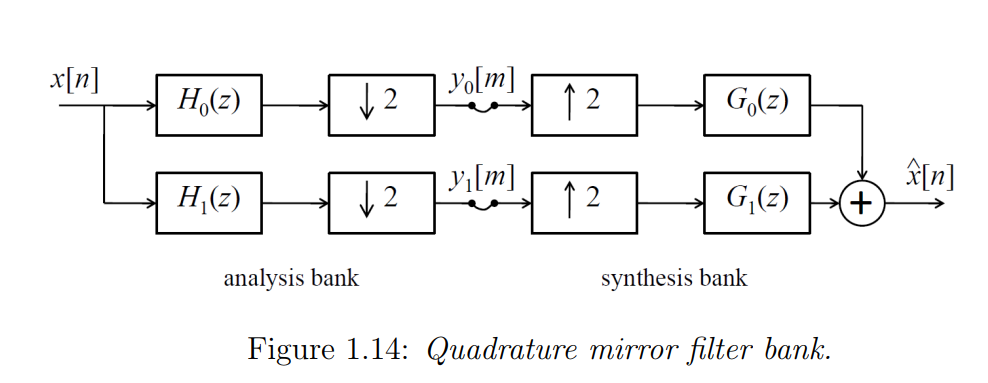

- 1 (H0 = Lowpass) Path for low frequenies, 1 Path for high frequencies (H1 =Highpass)

- Apparently this way one can lower informationloss 

- Input Signal: x[n]

- Analyzed Signals:x_hat[n]

- Synthesized Signal:y0[n],y1[n]

- **No Lowpassfiltering after Downsampling/ before Upsampling**

clc;
close all;
clear all;
path(path,'C:\Users\rdegi\Desktop\HS21\DSVB\Multirate Signal Processing and Filter Banks')

### Properties Analyzed Signals:

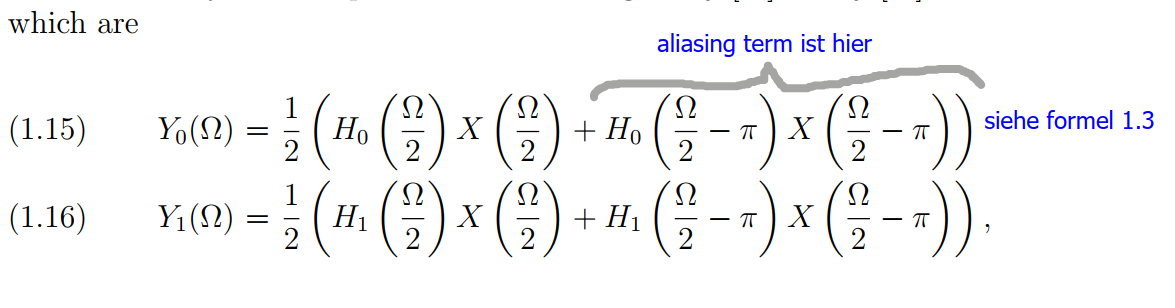

### Properties Synthesized Signal / Output Signal

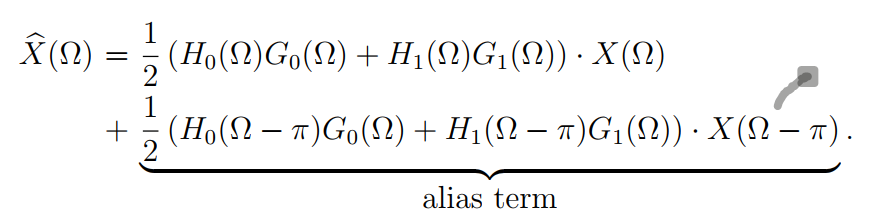

- Formula looks at normalized spectrum

- 0.5 of the signal is aliasing, 0.5 of the signal is usable

- There is aliasing!!!!

- The aliasing term consists of shiftet spectra

- only H and X spectra are shiftet

#### Aliasing

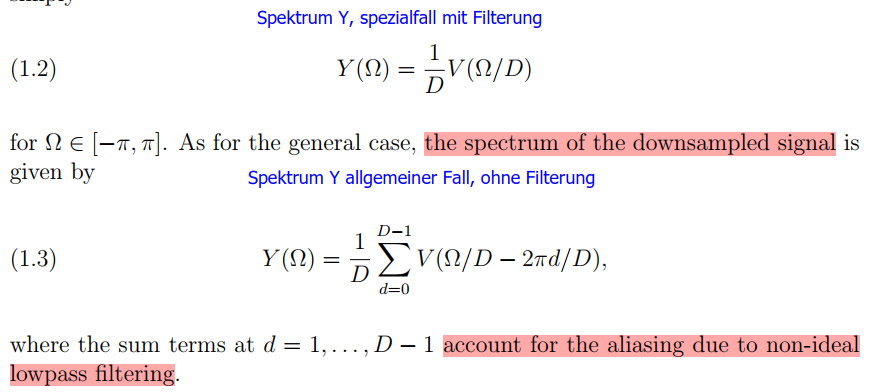

- The Formula 1.3 is the reason for the aliasing Term we have in X_hat

- Since we used a filter before while down or upsampling, we never had to deal with the aliasing term, which is not the case here

- In order to eliminate Aliasing, one has to equal the aliasingterm to 0:

                            

- The Aliasing term becomes 0 if we choose our H and G as follows:

                        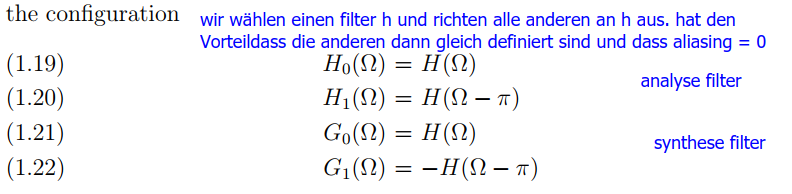

- If we choose our filters like this, we eliminate aliasing and we only have to define H, all the other terms ar similar to H, just H shifted and H multiplied with -1!

- The advantage of this is, that we only have to define one filter, and perfect reconstruction is guaranteed.

# 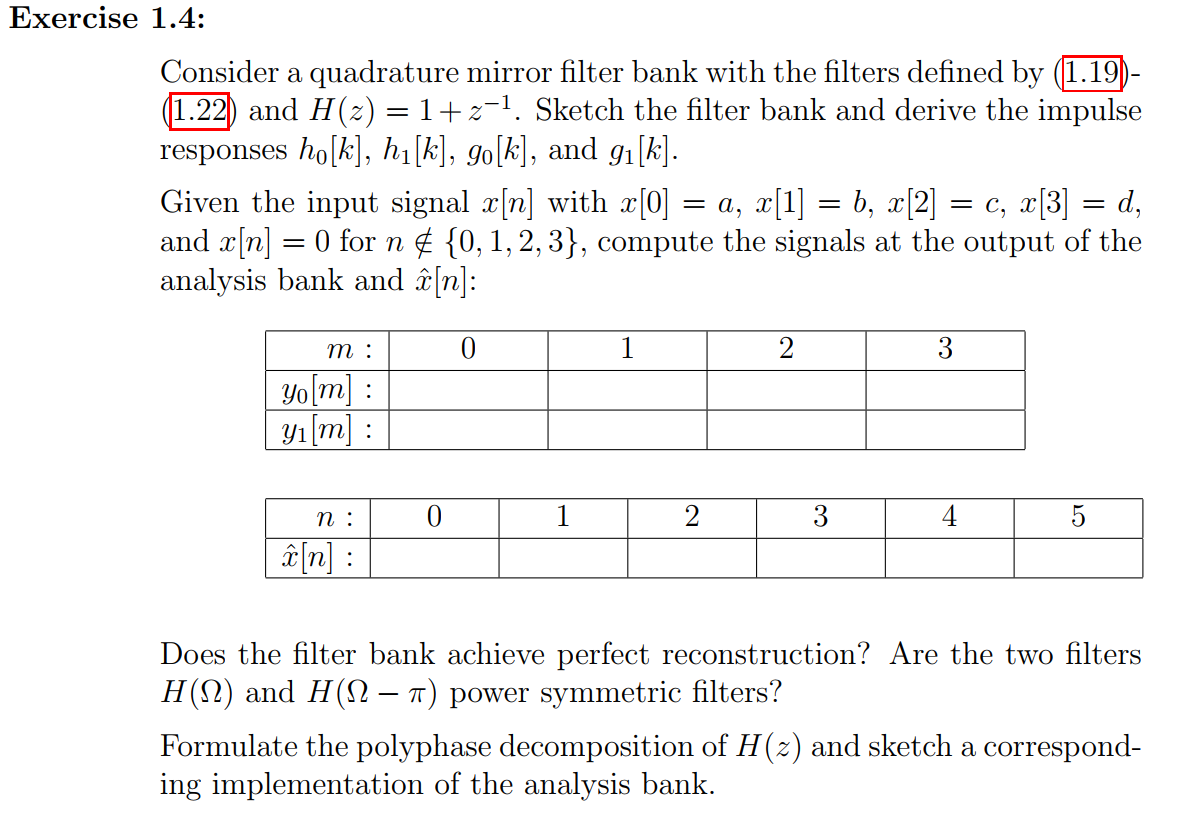

%define omega
omega = -pi:0.1:pi-0.1;
%define H0
H0_z=[1 1]; 
h0_n=impz(H0_z);
H0_omega=fftshift(freqz(H0_z,1,length(omega),'whole'));
%define H1
H1_z=[1 -1]; 
h1_n=impz(H1_z);
H1_omega=fftshift(freqz(H1_z,1,length(omega),'whole'));
%define G0
G0_z=[1 1]; 
g0_n=impz(H0_z);
G0_omega=fftshift(freqz(G0_z,1,length(omega),'whole'));
%define G1
G1_z=[-1 1]; 
g1_n=impz(G1_z);
G1_omega=fftshift(freqz(G1_z,1,length(omega),'whole'));

Display Impulserespnsens (Response of System time domain)

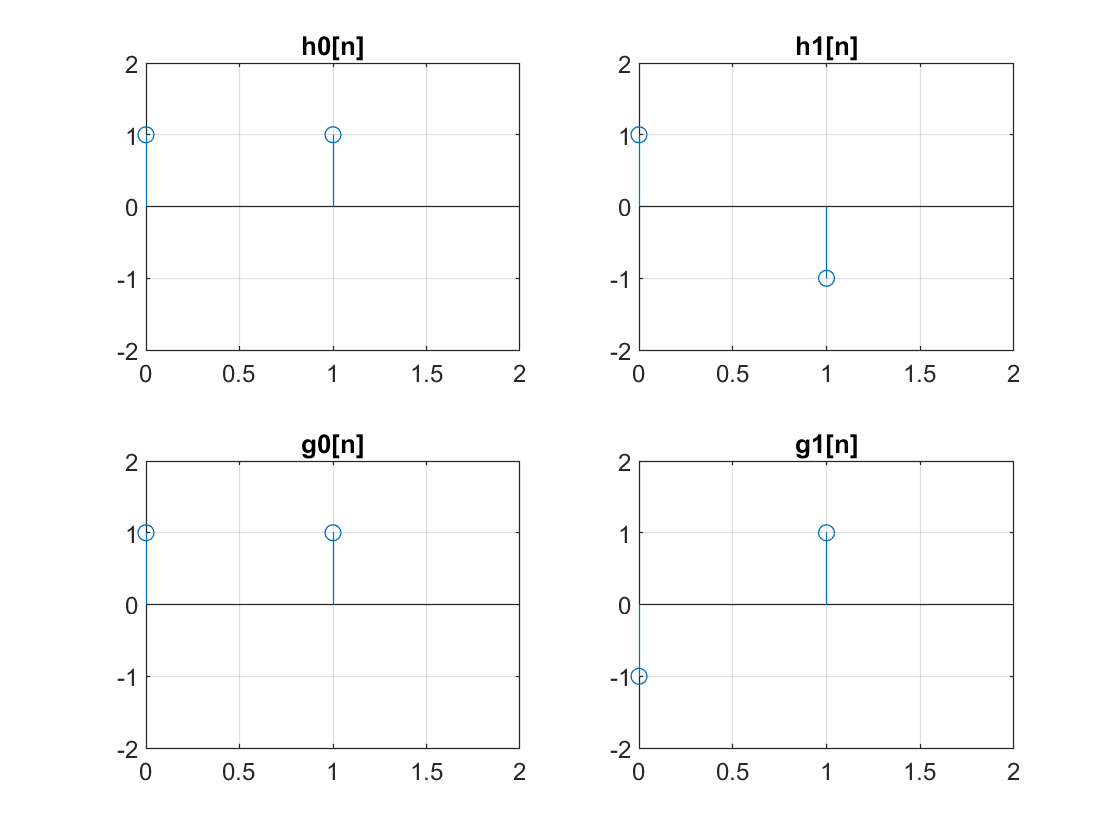

figure;
subplot(2,2,1)
stem([0 1],h0_n);
axis([0 2 -2 2])
grid on;
title('h0[n]')
subplot(2,2,2)
stem([0 1],h1_n);
axis([0 2 -2 2])
grid on;
title('h1[n]')
subplot(2,2,3)
stem([0 1],g0_n);
axis([0 2 -2 2])
grid on;
title('g0[n]')
subplot(2,2,4)
stem([0 1],g1_n);
axis([0 2 -2 2])
grid on;
title('g1[n]')

Display the continous frequency spectra (frequency domain)

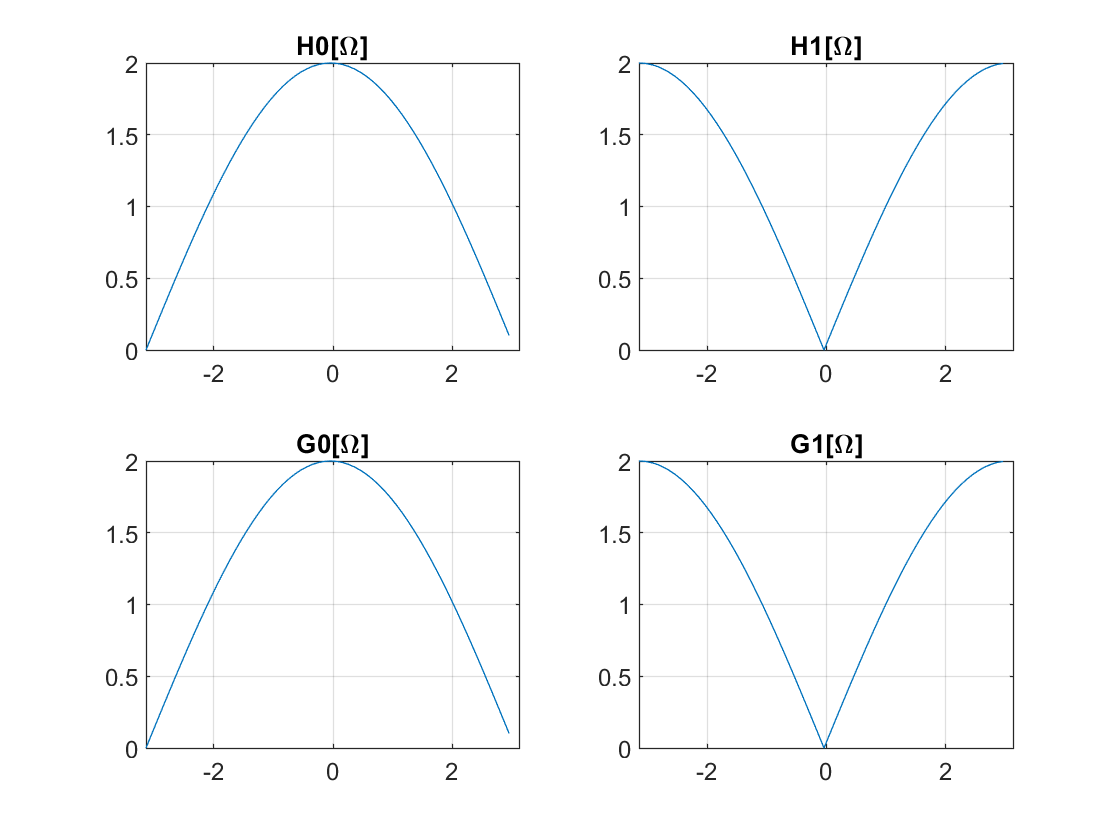

figure;
subplot(2,2,1)
plot(omega,abs(H0_omega))
axis([-pi pi 0 2])
grid on;
title('H0[\Omega]')
subplot(2,2,2)
plot(omega,abs(H1_omega))
axis([-pi pi 0 2])
grid on;
title('H1[\Omega]')
subplot(2,2,3)
plot(omega,abs(G0_omega))
axis([-pi pi 0 2])
grid on;
title('G0[\Omega]')
subplot(2,2,4)
plot(omega,abs(G1_omega))
axis([-pi pi 0 2])
grid on;
title('G1[\Omega]')

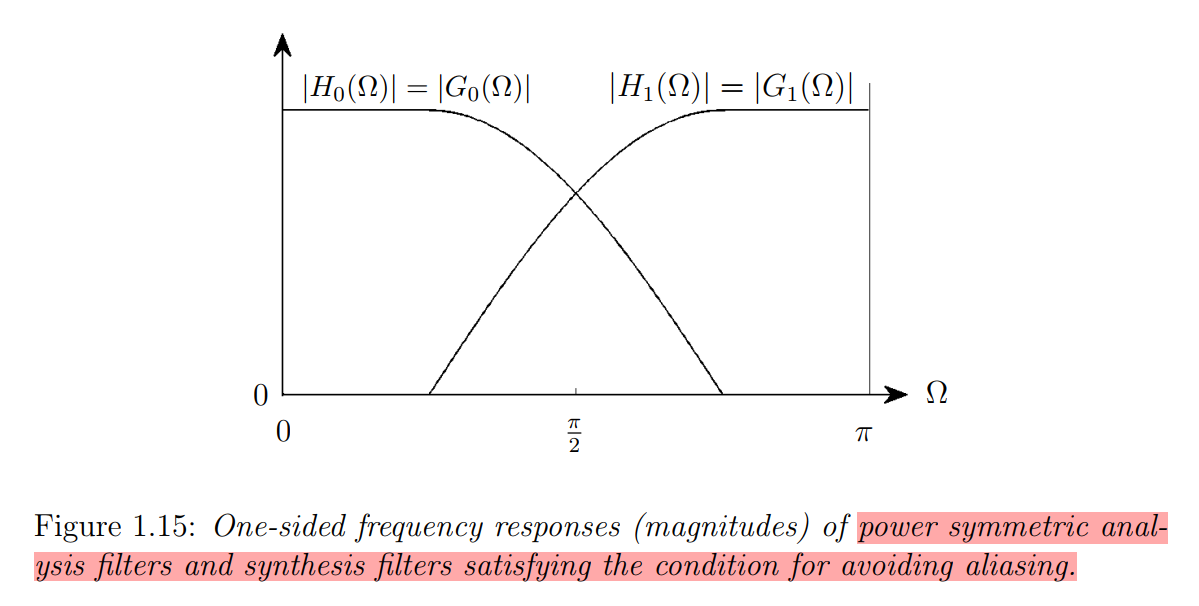

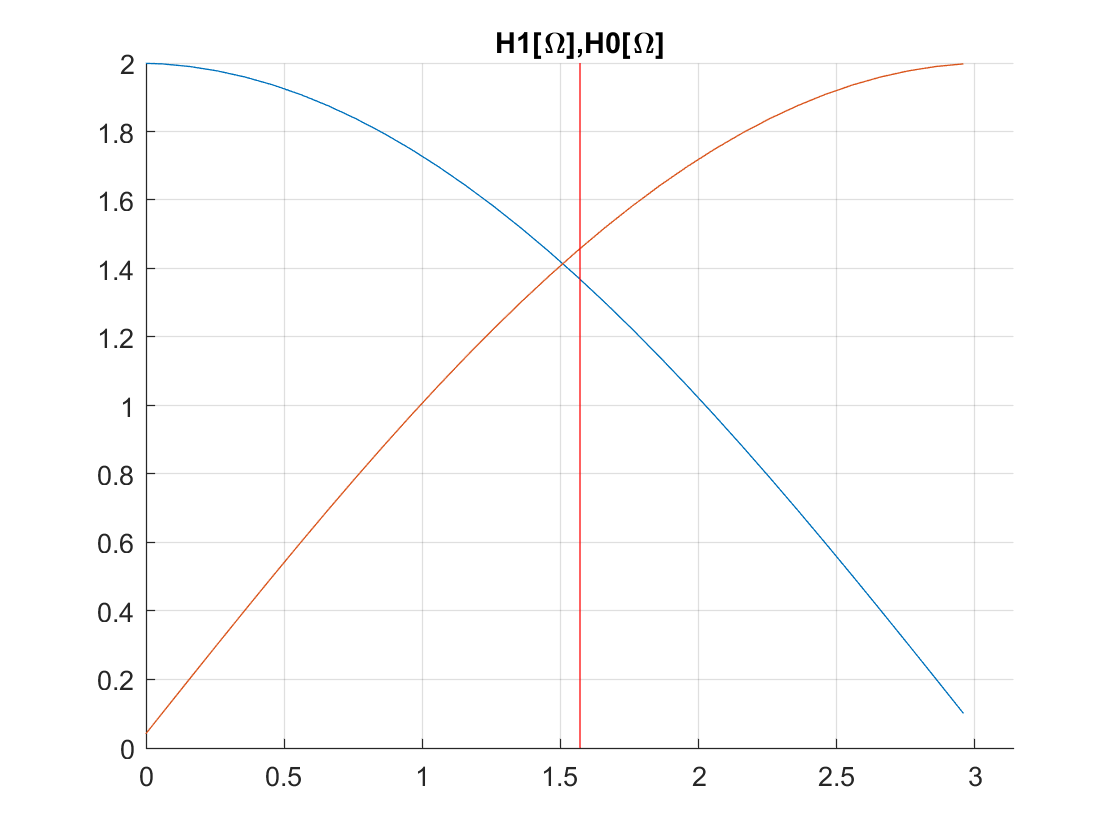

figure('Name','Check for powersymmetrie');
hold on;
plot(omega,abs(H0_omega))
plot(omega,abs(H1_omega))
line([pi/2 pi/2],[0 2],'color','red')
axis([0 pi 0 2])
title('H1[\Omega],H0[\Omega]')
hold off
grid on;

- **Why is the point |**`H_1`**|=|H_0| not at pi/2 ?`!!!!!!**

- **Perfect Reconstruction only works for certain filters, like powersymmetric filters**

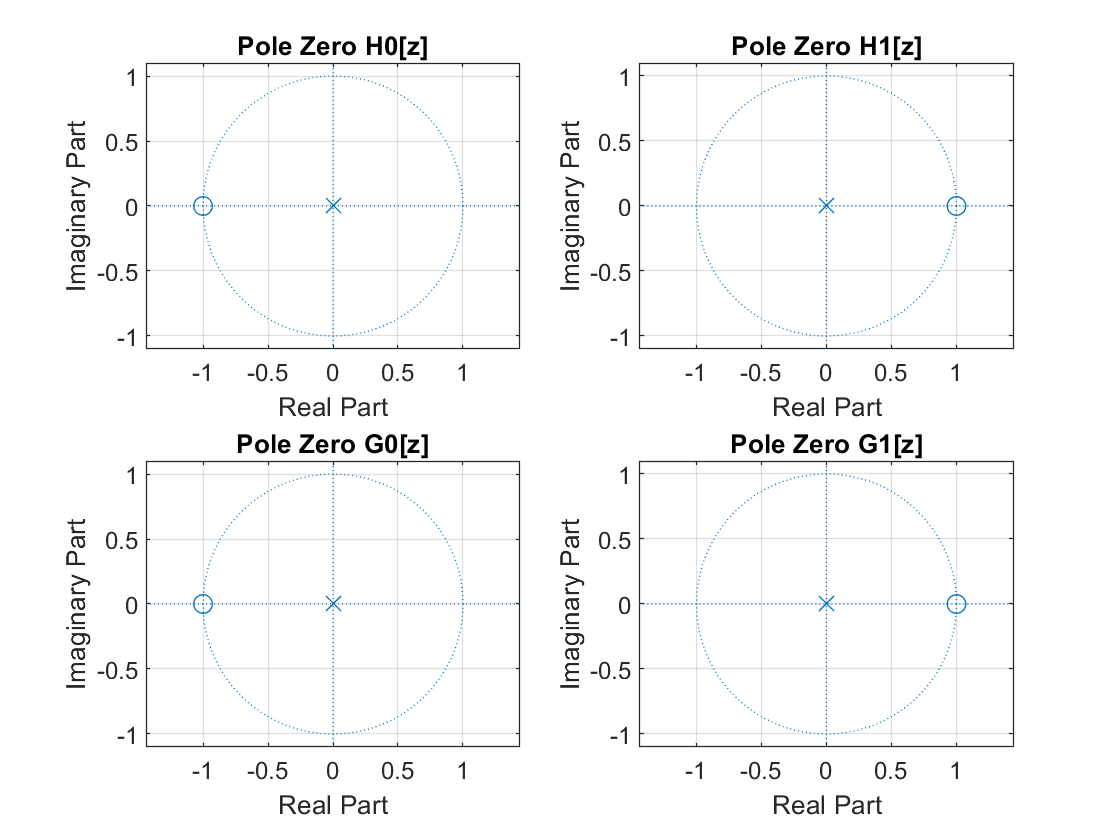

figure;
subplot(2,2,1)
zplane(H0_z);
grid on;
title('Pole Zero H0[z]')
subplot(2,2,2)
zplane(H1_z);
grid on;
title('Pole Zero H1[z]')
subplot(2,2,3)
zplane(G0_z);
grid on;
title('Pole Zero G0[z]')
subplot(2,2,4)
zplane(G1_z);
grid on;
title('Pole Zero G1[z]')

Get y1_n and y0_n

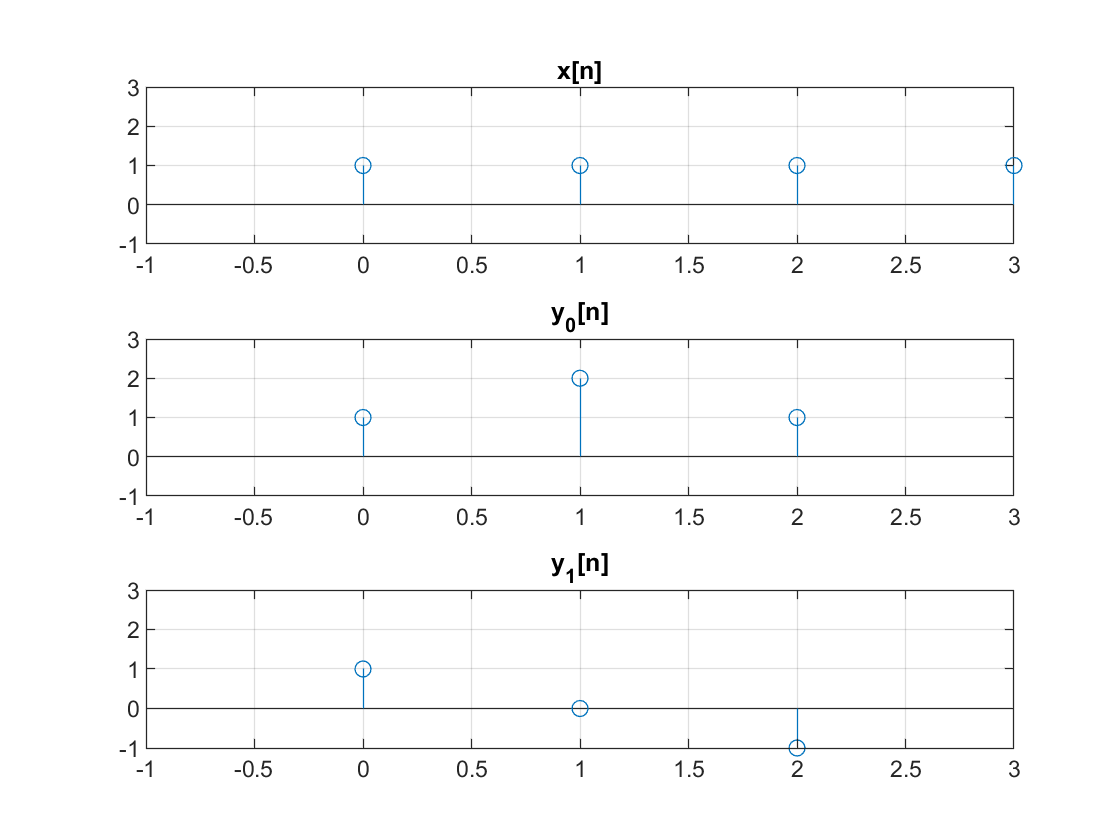

a=1;
b=1;
c=1;
d=1;
x_n=[a b c d];

%filter x_n with H0
x0_n=conv(x_n,h0_n);
%downsample x0_n
D=2;
y0_n=downsample(x0_n,D);

%filter x_n with H0
x1_n=conv(x_n,h1_n);
%downsample x0_n
D=2;
y1_n=downsample(x1_n,D);
figure;
subplot(3,1,1);
stem([0,1,2,3],x_n);
grid on;
title('x[n]')
axis([-1 3 -1 3]);
%y0/1_n
subplot(3,1,2);
stem([0,1,2],y0_n);
grid on;
title('y_0[n]')
axis([-1 3 -1 3]);
subplot(3,1,3);
stem([0,1,2],y1_n);
grid on;
title('y_1[n]')
axis([-1 3 -1 3]);

Second Half of Mirrorbank

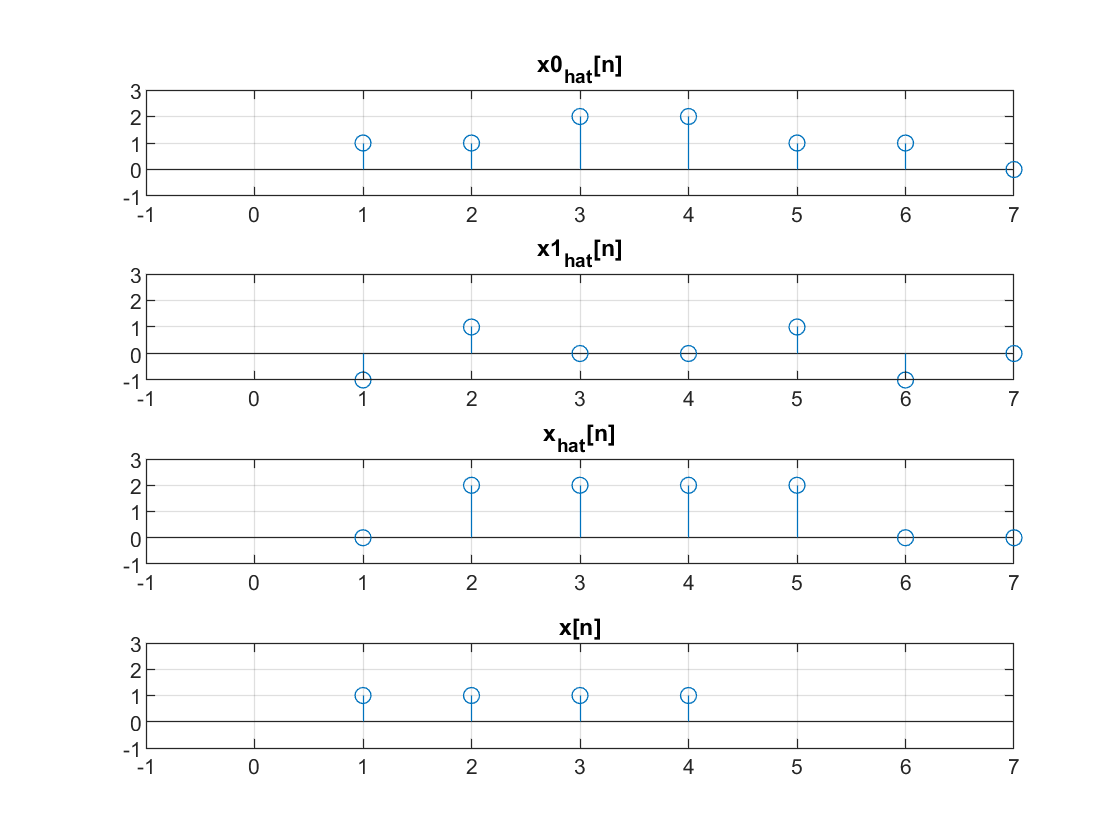

I=2;
%Upsampling of upper channel
y0_I=upsample(y0_n,I);
%filtering of upper channel 
x0_hat=conv(y0_I,g0_n);

%Upsampling of upper channel
y1_I=upsample(y1_n,I);
%filtering of upper channel 
x1_hat=conv(y1_I,g1_n);

x_hat=x1_hat+x0_hat;

figure;
subplot(4,1,1);
stem(x0_hat);
grid on;
title('x0_{hat}[n]')
axis([-1 7 -1 3]);
%y0/1_n
subplot(4,1,2);
stem(x1_hat);
grid on;
title('x1_{hat}[n]')
axis([-1 7 -1 3]);
subplot(4,1,3);
stem(x_hat);
grid on;
title('x_{hat}[n]')
axis([-1 7 -1 3]);
subplot(4,1,4)
stem(x_n);
grid on;
title('x[n]')
axis([-1 7 -1 3]);

x[n] has been shifted by one and scaled by a factor of two. Since perfect reconstruction allows scaling and timeshifting, it is clearly visible that the mirrorbank perfectly reconstructs the signal. 

**BOTTOMLINE: **

- **QuadratureMirrorFilters delay and scale a signal!**

- **If powersymmetric filters are used, perfect reconstruction is guaranteed!**

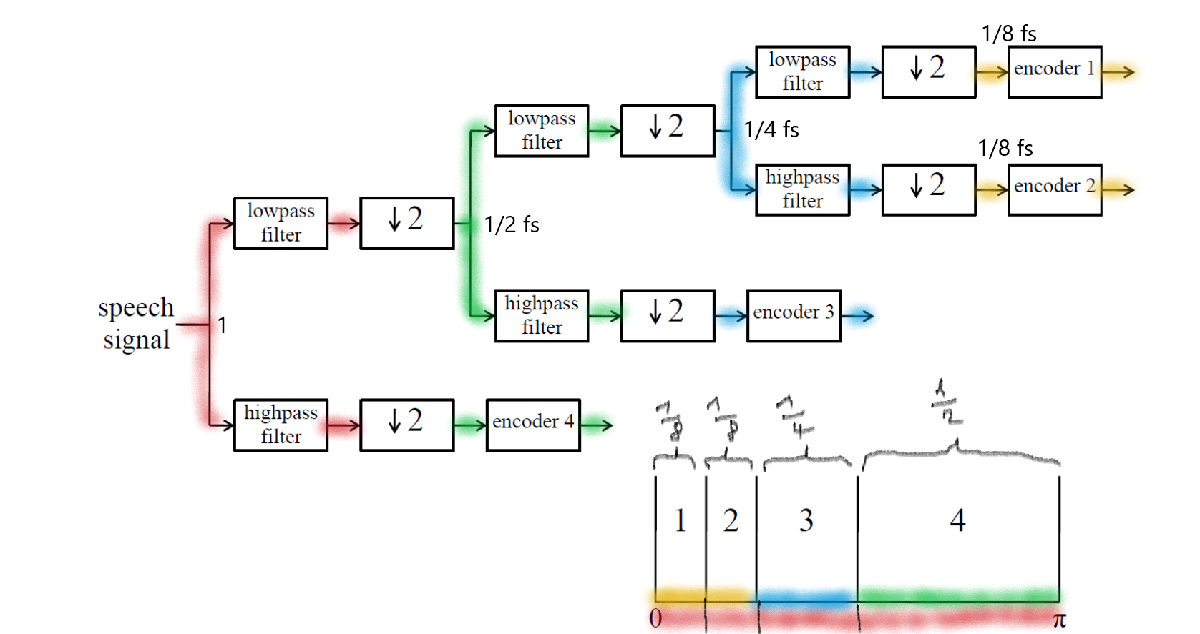

- Mantra: f_k=k*f_s/N

- Mantra: f_k=k*1/(T_s*N)

- Mantra: f_k=k*1/T

- Annahme: "Eine Array ist eine Periode", d.h je mehr elemente N im Array, desto grösser ist die Abtastrate f_s, d.h wenn man etwas downsampelt wird die Abtastrate kleiner.

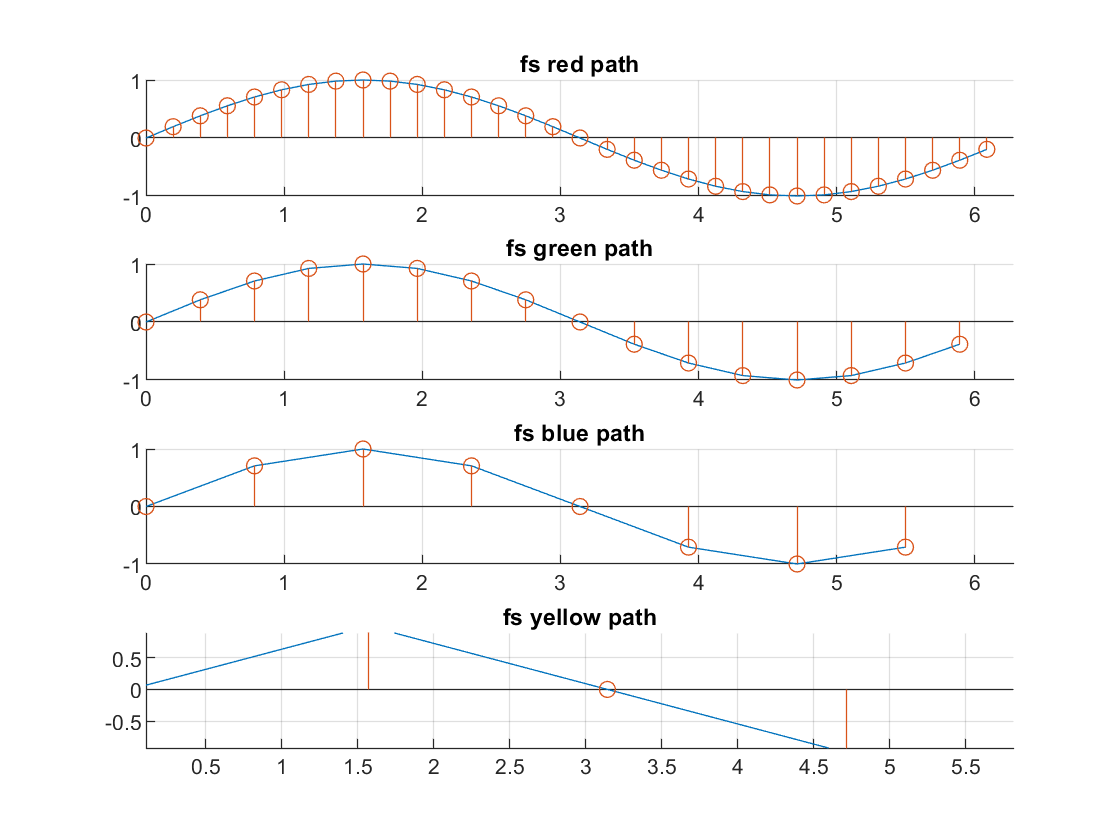

n=[0:31];
Ts_red=1/length(n);
red=sin(2*pi*n*Ts_red);
green=downsample(red,2);
blue=downsample(green,2);
yellow=downsample(blue,2);
figure;
subplot(4,1,1)
hold on
plot([0:2*pi/length(red):2*pi-2*pi/length(red)],red);
stem([0:2*pi/length(red):2*pi-2*pi/length(red)],red);
hold off;
title('fs red path')
grid on;
axis([0 2*pi -1 1]);
subplot(4,1,2)
hold on
plot([0:2*pi/length(green):2*pi-2*pi/length(green)],green);
stem([0:2*pi/length(green):2*pi-2*pi/length(green)],green);
hold off;
title('fs green path')
grid on;
axis([0 2*pi -1 1]);
subplot(4,1,3)
hold on
plot([0:2*pi/length(blue):2*pi-2*pi/length(blue)],blue);
stem([0:2*pi/length(blue):2*pi-2*pi/length(blue)],blue);
hold off;
title('fs blue path')
grid on;
axis([0 2*pi -1 1]);
subplot(4,1,4)
hold on
plot([0:2*pi/length(yellow):2*pi-2*pi/length(yellow)],yellow);
stem([0:2*pi/length(yellow):2*pi-2*pi/length(yellow)],yellow);
hold off;
title('fs yellow path')
axis([0 2*pi -1 1]);
grid on;

In the Image one can clearly see, that with  increasing time between sampling points, the samplerate decreases fs becomes smaller. So if you have two signals sampled at two different rates you also have to play them at different rates. For example, the signal in the blue path needs to be played twice as fast as the signal in the yellow path.

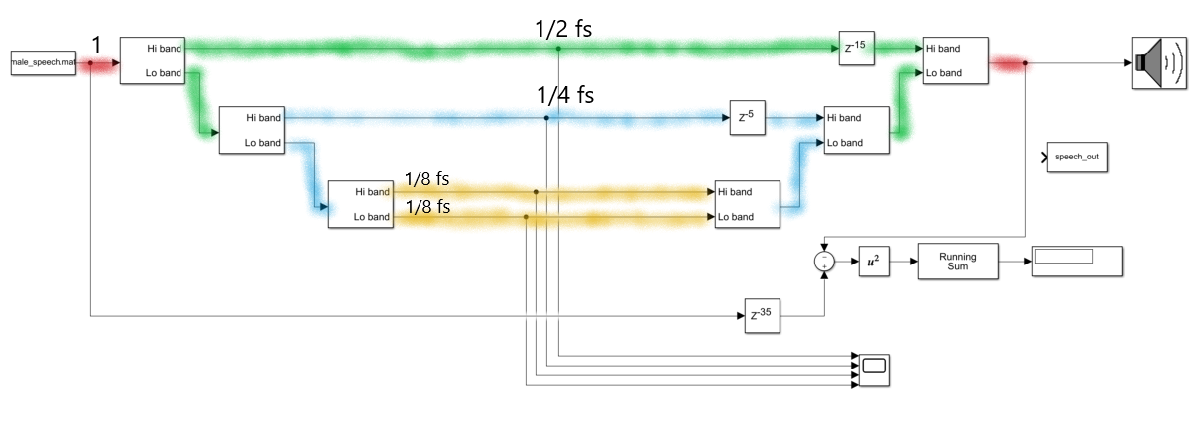

The Filterbank adds a delay of 5 samples. So between two yellow samples, there are 5 blue samples. This means, that the blue path has 5 more samples. Now the green path 

has to have twice as many samples as the blue, which means it needs 10 samples more, but the filterprocedure delays the signal by five, these five samples have to be added resulting in 15 extra samples for the green path. 

yellow=[1 1]; %length 2
%blue signal before entering mirrorbank
blue_no_delay=[1 0 0 1];%length 4
%green signal before entering mirrorbank
green_no_delay=[1 0 0 0 0 0 0 1];%length 8

%blue signal after entering mirrorbank
blue_with_delay=[0 0 0 0 0 1 0 0 1]; %length 4+5=9
%green signal after entering mirrorbank=2*length(blue signal after entering mirrorbank)
green_with_delay=[0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 0 0 0 0 0 0 1];%length=2*9+5=23
delay=length(green_with_delay)-length(green_no_delay)

the difference between green_with_delay and green_no_delay is 15 samples.